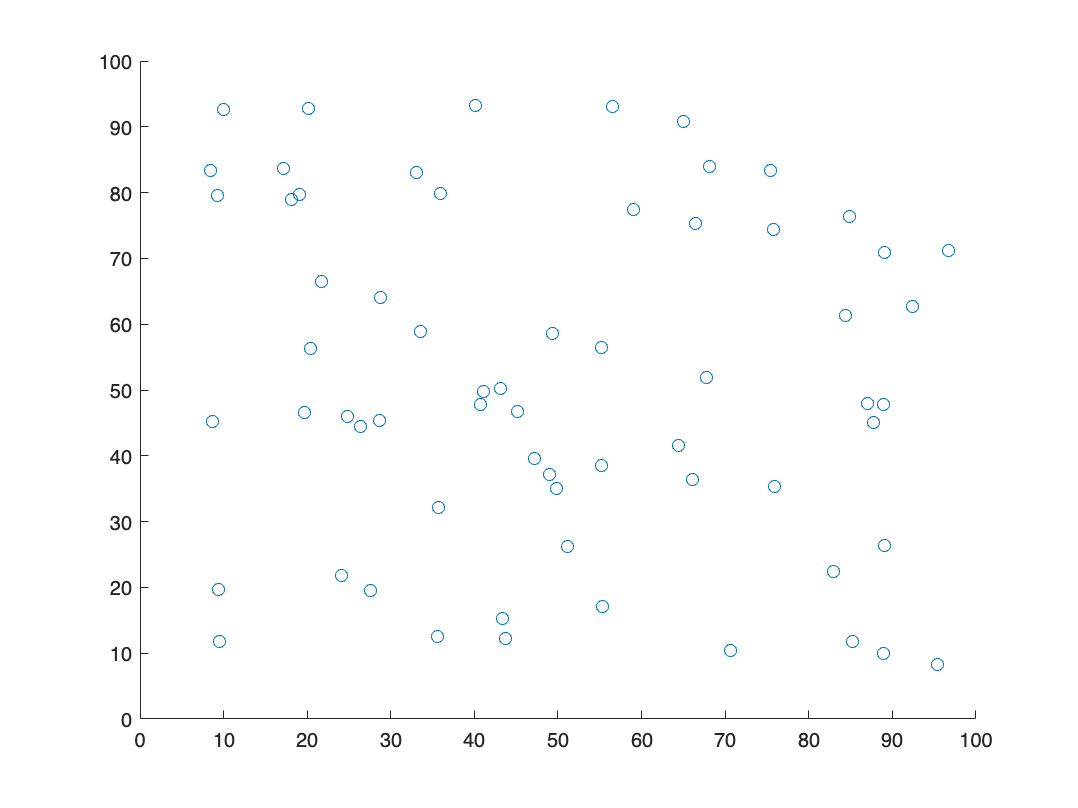

clear all
close all
clc

Array=csvread('graphdataset2.csv');
col1 = Array(:, 1);
col2 = Array(:, 2);
scatter(col1,col2)

T=readtable('graphdataset2.csv');
  
p=T{:,1:2};
save('mymat.mat','p')

load mymat

s=zeros(size(p,1),1);
s(1)=1;

G=gsp_graph(1,p);

GSP_CHECK_WEIGHTS: The diagonal of the weight matrix is not 0!


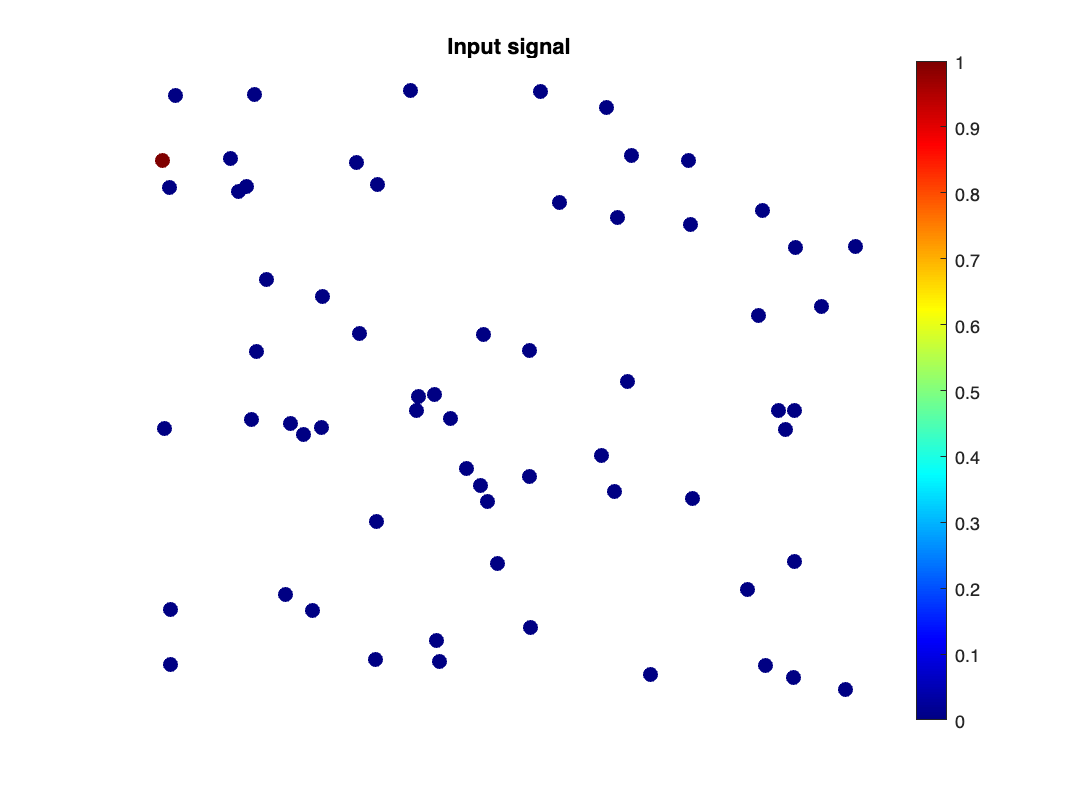

figure;gsp_plot_signal(G,s)
title('Input signal');